**Trayectoria 1: **

x = [0 a 5] F(x) = 2*sen(x²)

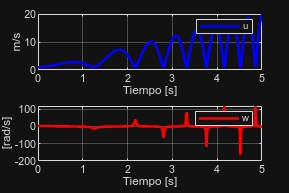

clear
close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 5;
ts = 0.01;                % paso pequeño porque la curva oscila rápido al final
t  = 0:ts:tf;
N  = length(t);

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1  = zeros(1,N+1);
y1  = zeros(1,N+1);
phi = zeros(1,N+1);

% En t=0: dy/dx = 4*0*cos(0) = 0  ->  phi(1) = atan(0) = 0
x1(1)  = 0;
y1(1)  = 0;               % F(0) = 2*sin(0) = 0
phi(1) = atan(0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1,N);
w = zeros(1,N);

for k = 1:N
    tk = t(k);
    
    % PASO 1
    % Definir la función de la trayectoria y su gráfica en el espacio
    % temporal.
    % Trayectoria:  y = 2*sin(x^2),  con  x = t
    
    
    % PASO 2  
    % Parametrizar en función del tiempo:
    %   x(t) = t
    %   y(t) = 2*sin(t^2)
    
    % PASO 3 
    % Calcular las derivadas para obtener las velocidades.
    %   dx/dt   = 1
    %   dy/dt   = 4t*cos(t^2)
    %   d2y/dt2 = 4*cos(t^2) - 8t^2*sin(t^2)

    dx  = 1;
    dy  = 4*tk*cos(tk^2);
    ddy = 4*cos(tk^2) - 8*tk^2*sin(tk^2);
    
    % Paso 4
    % Obtener la expresión matemática para la velocidad lineal u(t).
    %   u(t) = sqrt( (dx/dt)^2 + (dy/dt)^2 )
  
    u(k) = sqrt(dx^2 + dy^2);

    
    % Paso 5
    % Obtener la expresión matemática para la velocidad angular w(t).
    %   w(t) = d(theta)/dt = (d2y/dt2) / (1 + (dy/dt)^2)
    % ---------------------------------------------------------------------
    w(k) = ddy / (1 + dy^2);
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PASO 6: theta(t) se obtiene integrando w(t).
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;         
    
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-1 6 -3 3 0 2]);

scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);

step = 5;                  % saltar frames, con ts=0.01 serían 500 pasos
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')

**Trayectoria 2:**

X= [-4 a 4]

F(x) = x² + y² -16

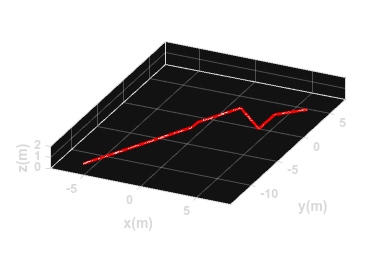

clear
close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 12;
ts = 0.01;
t  = 0:ts:tf;
N  = length(t);

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1  = zeros(1,N+1);
y1  = zeros(1,N+1);
phi = zeros(1,N+1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);

%%%%%%%%%%%%%%%%%%%%%% GENERACION DE LA TRAYECTORIA %%%%%%%%%%%%%%%%%%%%%%%
% Paso 1
% Definir la función de la trayectoria. Función a trozos:
%           { 2x       si x <= -1
%   y(x) =  { 2x + 1   si -1 < x < 1
%           { -x + 4   si  1 <= x < 4
%           { x - 1    si x >= 4

% Paso 2
% Parametrizar en función del tiempo:
%   x(t) = t - 6     (t=0 -> x=-6 ; t=12 -> x=6)
x_traj = t - 6;              % x(t)
y_traj = zeros(1,N);         % y(t)

for k = 1:N
    x = x_traj(k);
    if x <= -1
        y_traj(k) = 2*x;
    elseif x < 1
        y_traj(k) = 2*x + 1;
    elseif x < 4
        y_traj(k) = -x + 4;
    else
        y_traj(k) = x - 1;
    end
end

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1,N);
w = zeros(1,N);

% Paso 3
% Calcular las derivadas numéricas de x(t) e y(t):
for k = 1:N-1
    dx = (x_traj(k+1) - x_traj(k)) / ts;
    dy = (y_traj(k+1) - y_traj(k)) / ts;
    
    % Paso 4
    % Velocidad lineal:  u(t) = sqrt( (dx/dt)^2 + (dy/dt)^2 )
    u(k) = sqrt(dx^2 + dy^2);
    
    % Paso 5
    % Ángulo de orientación:  theta(t) = atan2(dy/dt, dx/dt)
    theta_k = atan2(dy, dx);
    
    if k == 1
        phi_prev = theta_k;
    end
    
    % Paso 6
    % Velocidad angular:  w(t) = d(theta)/dt ~ (theta(k+1) - theta(k))/ts
   
    w(k) = (theta_k - phi_prev) / ts;
    phi_prev = theta_k;
end
u(N) = u(N-1);
w(N) = 0;

%%%%%%%%%%%%%%%%%%%%%%%% CONDICION INICIAL DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%
x1(1)  = x_traj(1);           % -6
y1(1)  = y_traj(1);           % -12
phi(1) = atan2(y_traj(2)-y_traj(1), x_traj(2)-x_traj(1));
hx(1)  = x1(1);
hy(1)  = y1(1);

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-8 8 -14 8 0 2]);

scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);

step = 5;
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

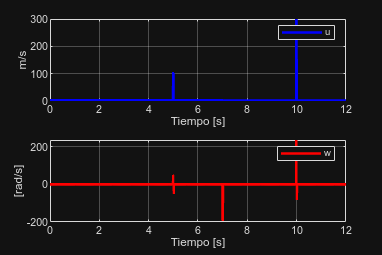


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')